% 3.7
% given
gc = 32.174;  % conversion
g0 = 32.174;  % accel due to gravity
gamma = 1.3;
epsilon = 2.3;
At = 5/144; % ft^2
R = 66;
Tc = 5300;
psi2lbf = 144;
pa = 10;
Pc = [300 200 100]';
c1 = (gamma+1)/(gamma-1)

c1 = 7.6667

c2 = inv(gamma-1)

c2 = 3.3333

c3 = inv(gamma)

c3 = 0.7692

c4 = gamma/(gamma-1)

c4 = 4.3333

c5 = inv(c4)

c5 = 0.2308

M = 2.264;
A2 = At*epsilon

A2 = 0.0799

Pc2Pe = 1/(1+0.5*(gamma-1)*M^2)^(gamma/(gamma-1))

Pc2Pe = 0.0845


Pe = Pc2Pe*Pc

Pe =    25.3390
   16.8926
    8.4463


P32Pc = pa./Pc

P32Pc =     0.0333
    0.0500
    0.1000



% a) Pc/Pa 

Pratio = Pc/pa;

% b) V_effective

Ve = sqrt((2*c4*R*Tc*(1-Pc2Pe^c5)*gc))

Ve = 6.5113e+03



% c) V2_ideal for epsilon_opt and epsilon_actual -- Pe = Patm

epsilon_inv = (0.5*(gamma+1))^c2.*(P32Pc).^c3.*sqrt(c1.*(1-P32Pc.^c5))

epsilon_inv =     0.2377
    0.3111
    0.4819



epsilon_ideal = epsilon_inv.^(-1)

epsilon_ideal =     4.2062
    3.2142
    2.0751



M_i = [2.825 2.577 2.162]';
V_ideal = M_i .* sqrt(gamma * gc*R*Tc)

V_ideal = 1.0e+04 *

    1.0806
    0.9857
    0.8270



V2_actual = M * sqrt(gamma*gc*R*Tc)

V2_actual = 8.6599e+03


% d) m_dot

m_dot = psi2lbf*At.*Pc.*gamma.*sqrt((2/(gamma+1))^c1)/(sqrt(gamma*R*Tc*g0))*gc

m_dot =     9.5991
    6.3994
    3.1997



% e) thrust
F = m_dot * V2_actual + (Pe-pa)*psi2lbf*A2

F = 1.0e+04 *

    8.3303
    5.5497
    2.7691



% f) Isp
Isp = F/(m_dot*g0)

Isp =   269.7280         0         0
  179.6946         0         0
   89.6611         0         0



% g) P_exit

Pe = Pc * Pc2Pe

Pe =    25.3390
   16.8926
    8.4463



% h) T_exit

Tc2Te = 1+(0.5*(gamma-1)*M^2)

Tc2Te = 1.7689

Te = Tc/Tc2Te/1000

Te = 2.9963

## 3.11



Pc = 20; % atm
gamma = 1.2;
atm2Pascal = 101325;
Pc_si = Pc*atm2Pascal;

% https://www.engineeringtoolbox.com/standard-atmosphere-d_604.html

%h = (0:100:50000)';
h = [0
1000
2000
3000
4000
5000
6000
7000
8000
9000
10000
15000
20000
25000
30000
40000
50000];

%Patm = 101325*(1-(2.25577e-5.*h)).^5.25588

Patm = 1.0e+05 *

   1.0132 + 0.0000i
   0.8987 + 0.0000i
   0.7950 + 0.0000i
   0.7011 + 0.0000i
   0.6164 + 0.0000i
   0.5402 + 0.0000i
   0.4718 + 0.0000i
   0.4106 + 0.0000i
   0.3560 + 0.0000i
   0.3074 + 0.0000i


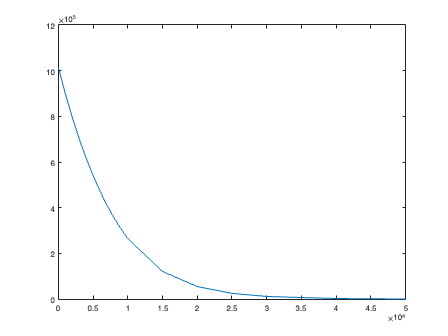

Patm = [10.13
8.988
7.95
7.012
6.166
5.405
4.722
4.111
3.565
3.08
2.65
1.211
0.5529
0.2549
0.1197
0.0287
0.007978]*10e4;


epsilon_inv = ((gamma+1)/2)^c2 .* (Patm./Pc_si).^c3 .* sqrt(c1.*(1-(Patm./Pc_si).^c5))

epsilon_inv =     0.8582
    0.8419
    0.8162
    0.7838
    0.7464
    0.7057
    0.6629
    0.6189
    0.5744
    0.5303


epsilon_var = (epsilon_inv).^(-1)

epsilon_var =     1.1653
    1.1878
    1.2251
    1.2759
    1.3397
    1.4170
    1.5086
    1.6158
    1.7408
    1.8857


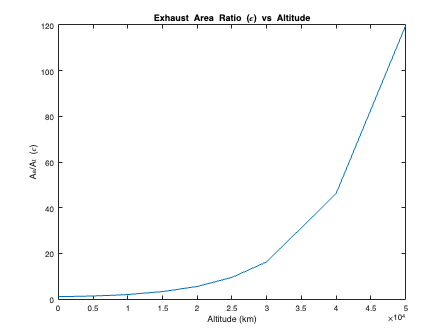


plot(h,epsilon_var)
title("Exhaust Area Ratio (\epsilon) vs Altitude")
xlabel("Altitude (km)")
ylabel("A_e/A_t (\epsilon)")